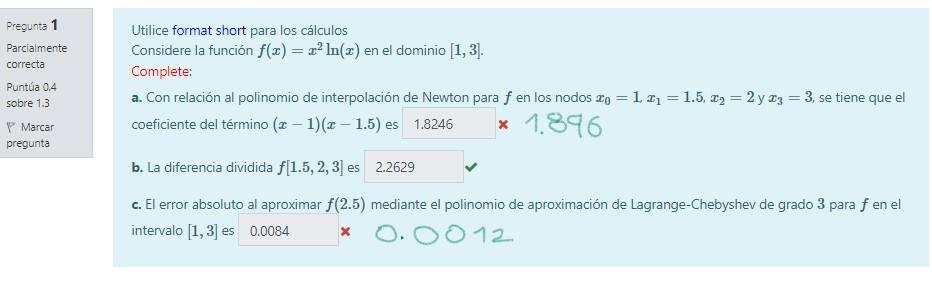

f = @(x) (x.^2).*(log(x));
format short
a = 1;
b=3;
X = [1 1.5 2 3];
Y = f(X)
[C, D] = newpoly (X, Y)


a) Es 1.8960

b) 2.2629 (ultima fila, penultimo numero)

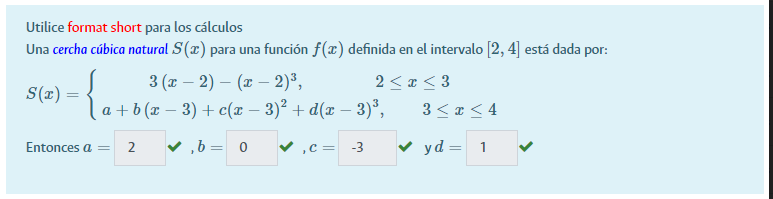

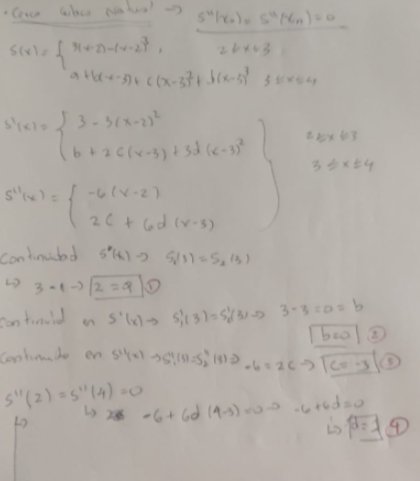

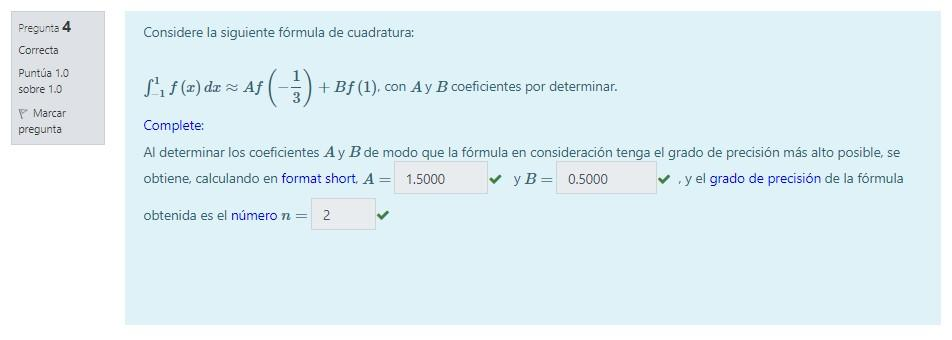

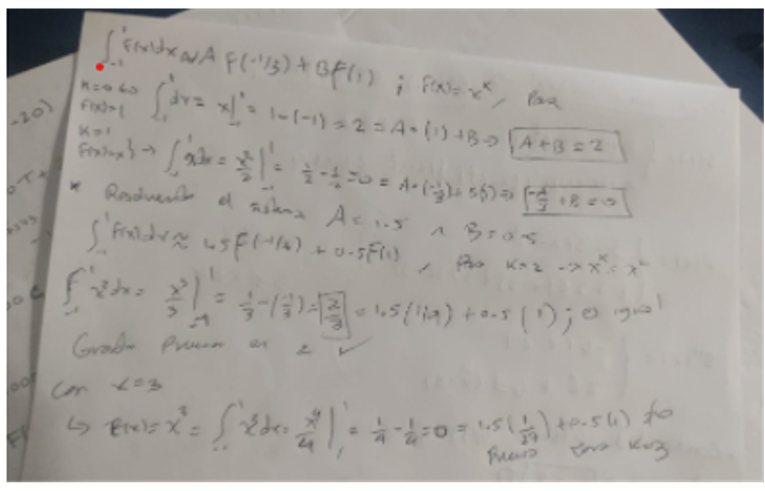

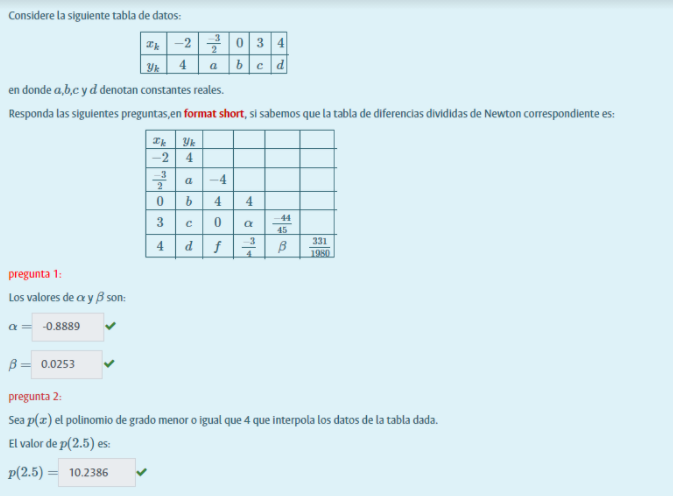

x = [-2 -3/2 0 3 4]
y = [3 2 8 8 5] % Esto se calculo hallando a,b,c,d,f con ayuda de la tabla
[Cn, D] = newpoly (x, y)

polyval(Cn,2.5) %RARO

[Cl, L] = lagran (x, y)
polyval(Cl,2.5)

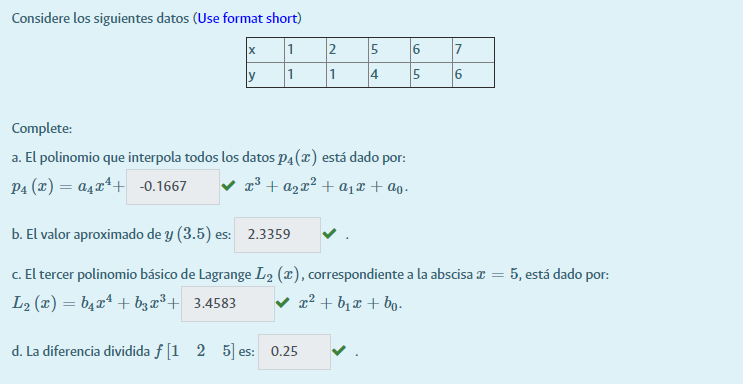

% A
x = [1 2 5 6 7]
y = [1 1 4 5 6]
[Cn, D] = newpoly (x, y) % El x^3 es de -0.1667
% D es 0.25

% B
polyval(Cn,3.5) % Es 2.3359

% C
[Cl, L] = lagran (x, y) % El L_3 en su x^2 es 3.4583


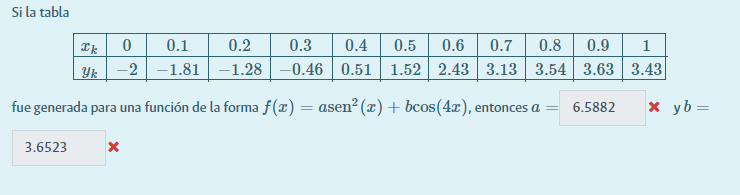

x= 0:0.1:1
y = [-2 -1.81 -1.28 -0.46 0.51 1.52 2.43 3.13 3.54 3.63 3.43]
C = lspoly (x, y,1) %   NI IDEA

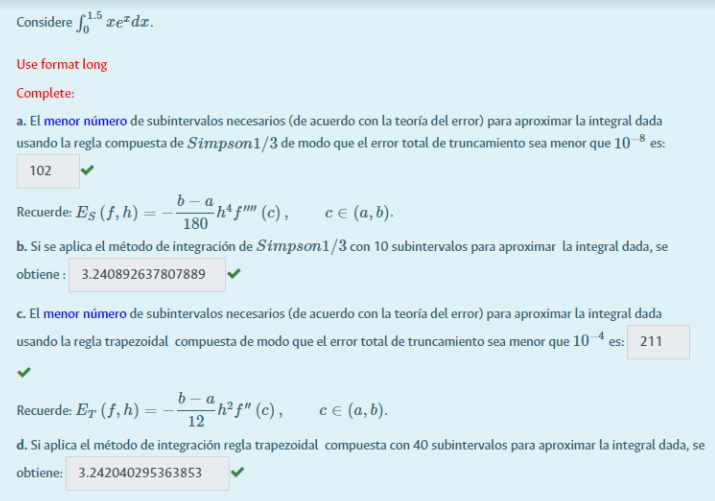

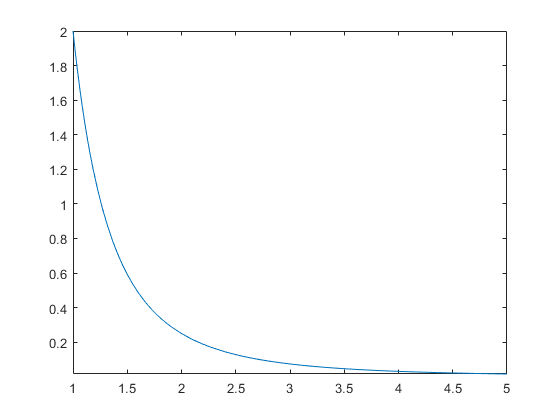

clear all 
syms x n

% ERROR COMPUESTA SIMPSON 1/3 (BUSCAMOS LA n)


%Solo es asignar los valores de f,a,b,error
%y observar en la grafica el punto maximo y 
%evaluarlo en u, en este caso cero es el maximo
%en a,b según la grafica. n es la salida, recordar
%que es una funcion techo y se toma el entero más cercano

f=x*log(x);
a=1;
b=5;
error=1e-9;



g=diff(f,4);
fplot(g,[a,b])

g=matlabFunction(g);

u=abs(g(a));

h=(b-a)/n;
err=((b-a)*(h^4)*u)/180;
k=solve(err==error,n);
N=(k(2,:)); 
m=vpa(N);
y=round(m);
z=0;
if y-m<0
    z=round(y+1);
end
if y-m>0
    z=y;
end
if mod(z,2)==0
    n1=z
else
    n1=z+1
end

$$n1 = 328$$

f=@(x) x.*log(x);
a= 1

a = 1

b=5

b = 5

format long
s = simprl (f, a, b, 30) % listo

s =   14.117975569538158


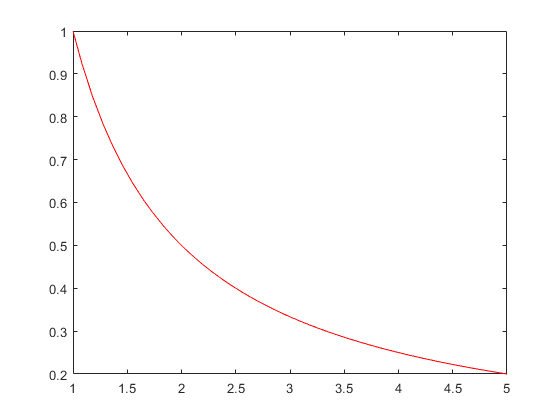

%  ERROR TRAPEZOIDAL COMPUESTO 

clear all 
syms x n

%Solo es asignar los valores de f,a,b,error
%y observar en la grafica el punto maximo y 
%evaluarlo en u, en este caso cero es el maximo
%en a,b según la grafica. n es la salida, recordar
%que es una funcion techo y se toma el entero más cercano

f=x*log(x);
a=1;
b=5;
error=1e-4;


g=diff(f,2);
g=matlabFunction(g);
fplot(g,[a,b],'r')

u=abs(g(b));
h=(b-a)/n;
err=((b-a)*(h^2)*u)/12;
k=solve(err==error,n);
N=k(2,:);
m=vpa(N);
y=round(m);
if y-m<0
    n1=round(y+1)
end

$$n1 = 104$$

if y-m>0
    n1=y
end

f=@(x) x.*log(x);
s = traprl (f, a, b, 100) 

s =   14.118188493735390


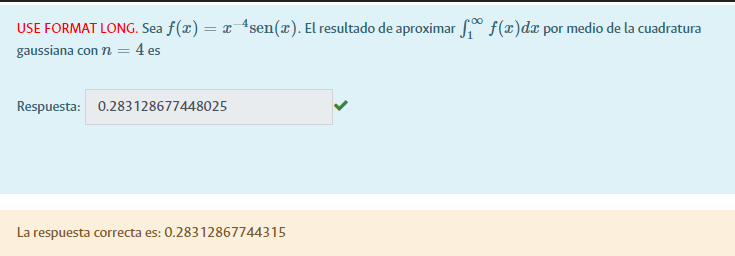

% INTEGRAL IMPROPIA
format long
syms x
f = x^(-4)*sin(x);
f = matlabFunction(f,"vars",{x});
a=1;
b=inf;
N = 4 % Cantidad de nodos;
[quad, raices, nodos, coefs] = impropias(f, a, b, N) %Esta funcion calcula integrales
%Impropias

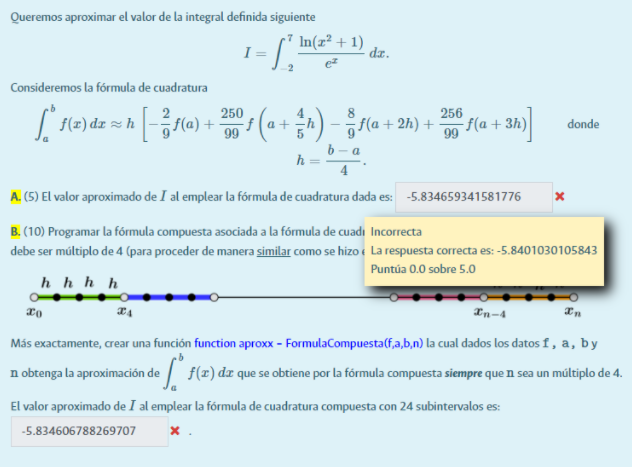

prueba:

format short
a=0; b=12 ;M = 12; h = (b-a)/12;
x=a:h:b
xa = (a+4/5*h):h:b % Una de las condiciones extrañas
xa(1:4:b)

x(1)
x(1:4:b)
x(3:4:b)
x(4:4:b)


s1 = -2/9*f(x(1:4:b))
s3 = -8/9*f(x(3:4:b)) 
s4 = 256/99*f(x(4:4:b))
s2 = 250/99*f((a+4/5*h):h:b)

% Se reemplaza el valor por M de tal manera que el codigo para la rutina
% queda como

s1 = -2/9*f(x(1:4:M))
s3 = -8/9*f(x(3:4:M)) 
s4 = 256/99*f(x(4:4:M))
s2 = 250/99*f((a+4/5*h):h:M)
s= h*(s1+s2+s3+s4)

% Se crea la rutina Cuadratura_M4

f = @(x) log(x.^2+1)./(exp(x))
format long
a= -2; b= 7; M = 4;
s = Cuadratura_M4(f,a,b,M)

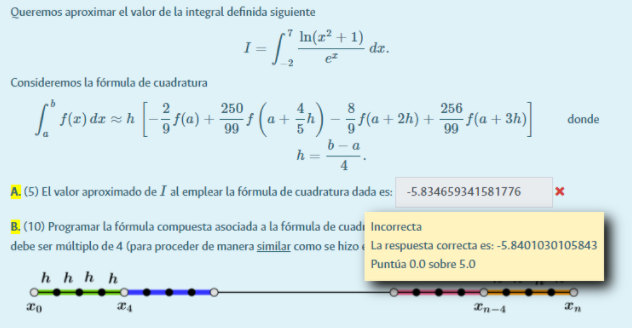

a=-2;
b=7;
f = @(x) log(x.^2+1)./(exp(x));
M =4;
s = Cuadratura_M4(f,a,b,4) % MELISIMO

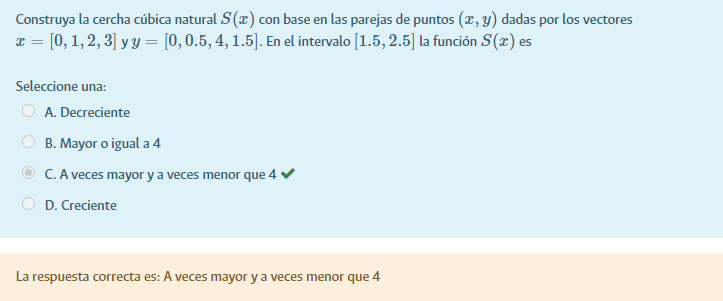

x = [0 1 2 3];
y = [0 0.5 4 1.5];
format short
S=csnatural(x,y);

GraficaCercha(x,y,S)
xlim([1.5 2.5])
hold on
hold off

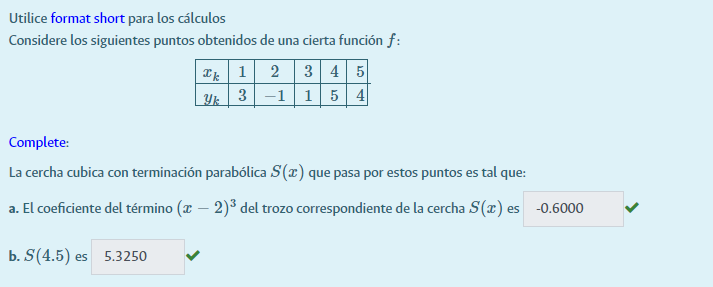

x = [1 2 3 4 5];
y = [3 -1 1 5 4];

S=csconstante(x,y)

polyval(S(4,:),4.5-4) % Melo

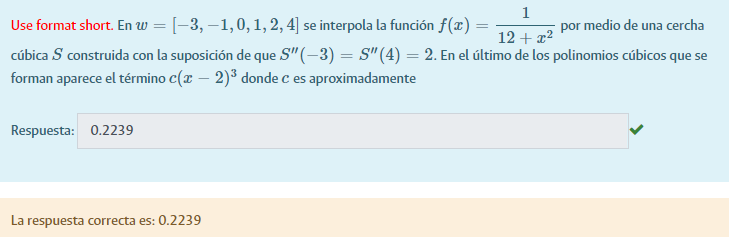

X = [-3 -1 0 1 2 4];
f = @(x) 1./(12+x.^2);
Y = f(X);

S=csconocido(X,Y,2,2) % Melo

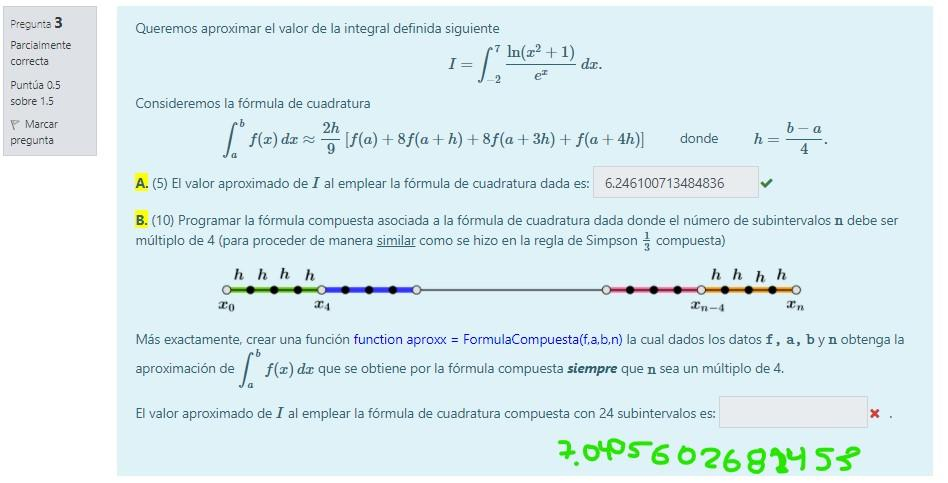

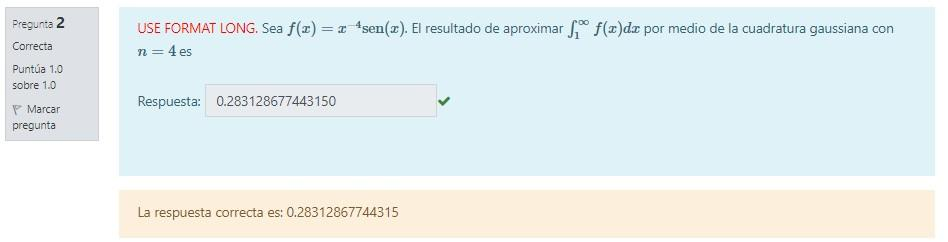

% INTEGRAL IMPROPIA
syms x
f = x^(-4)*sin(x);
f = matlabFunction(f,"vars",{x});
a=1;
b=inf;
N = 4 % Cantidad de nodos;
[quad, raices, nodos, coefs] = impropias(f, a, b, N) %Esta funcion calcula integrales
%Impropias

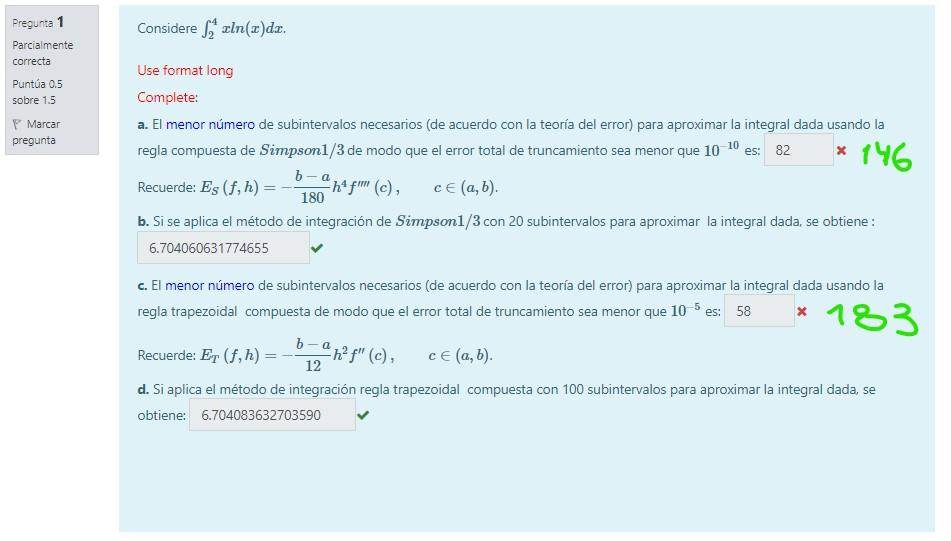

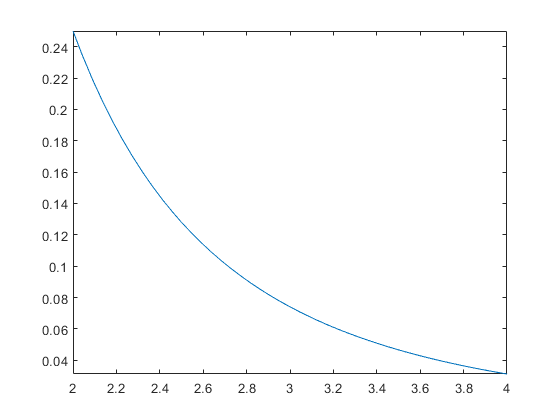

clear all 
syms x n

hold off

%Solo es asignar los valores de f,a,b,error
%y observar en la grafica el punto maximo y 
%evaluarlo en u, en este caso cero es el maximo
%en a,b según la grafica. n es la salida, recordar
%que es una funcion techo y se toma el entero más cercano

f=x*log(x);
a=2;
b=4;
error=1e-10;



g=diff(f,4);
fplot(g,[a,b])

g=matlabFunction(g);
u=abs(g(a));
h=(b-a)/n;
err=((b-a)*(h^4)*u)/180;
k=solve(err==error,n);
N=(k(2,:)); 
m=vpa(N);
y=round(m);
z=0;
if y-m<0
    z=round(y+1);
end
if y-m>0
    z=y;
end
if mod(z,2)==0
    n1=z
else
    n1=z+1
end

$$n1 = 146$$


% MELO

f=@(x) x.*log(x);
a=2;
b=4;
format long
s = simprl (f, a, b, 20)

s =    6.704060631774655


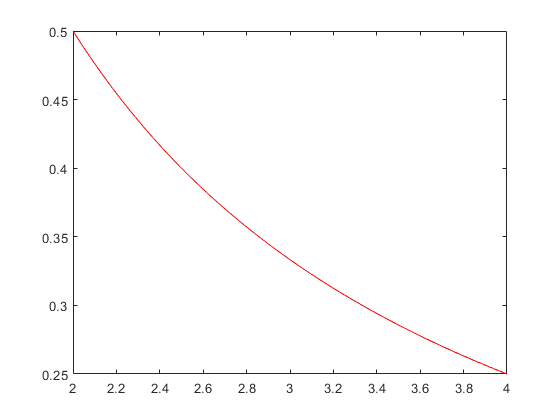

format short
clear all 
syms x n

%Solo es asignar los valores de f,a,b,error
%y observar en la grafica el punto maximo y 
%evaluarlo en u, en este caso cero es el maximo
%en a,b según la grafica. n es la salida, recordar
%que es una funcion techo y se toma el entero más cercano

f=x*log(x);
a=2;
b=4;
error=1e-5;



g=diff(f,2);
g=matlabFunction(g);
fplot(g,[a,b],'r')

u=abs(g(a));
h=(b-a)/n;
err=((b-a)*(h^2)*u)/12;
k=solve(err==error,n);
N=k(2,:);
m=vpa(N);
y=round(m);
if y-m<0
    n1=round(y+1)
end
if y-m>0
    n1=y
end

$$n1 = 183$$

f=@(x) x.*log(x);
a=2;
b=4;
s = traprl (f, a, b, 100) 

s = 6.7041

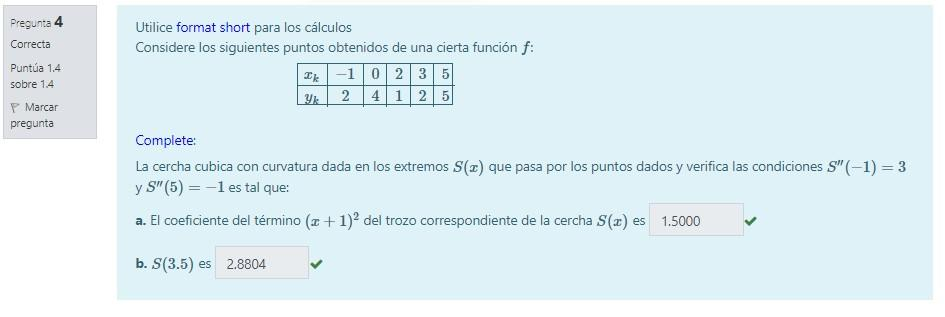

X = [-1 0 2 3 5];
Y = [2 4 1 2 5];
S=csconocido(X,Y,3,-1)

S =    -1.4050    1.5000    1.9050    2.0000
    0.8100   -2.7151    0.6900    4.0000
   -0.6953    2.1452   -0.4498    1.0000
   -0.0932    0.0591    1.7545    2.0000


polyval(S(4,:),3.5-3)

ans = 2.8804

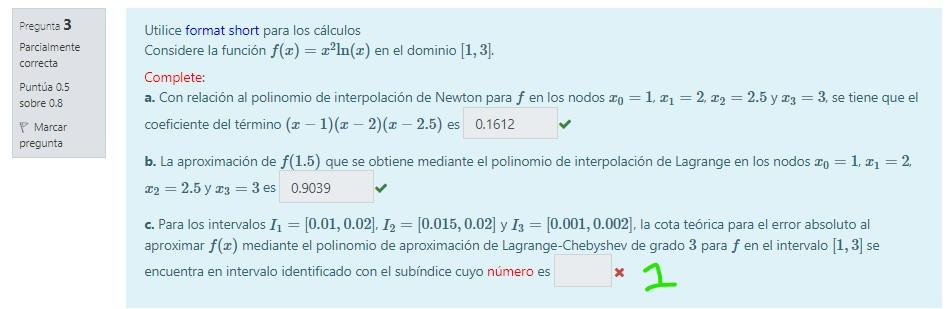

f = @(x) x.^2.*log(x);
a = 1; b=3;
X= [1 2 2.5 3]

X =     1.0000    2.0000    2.5000    3.0000


Y = f(X)

Y =          0    2.7726    5.7268    9.8875


[C, D] = newpoly (X, Y) % 0.1621 el inciso a

C =     0.1612    1.2041   -1.9680    0.6027


D =          0         0         0         0
    2.7726    2.7726         0         0
    5.7268    5.9085    2.0906         0
    9.8875    8.3214    2.4129    0.1612


[C, L] = lagran (X, Y)

C =     0.1612    1.2041   -1.9680    0.6027


L =    -0.3333    2.5000   -6.1667    5.0000
    2.0000  -13.0000   26.0000  -15.0000
   -2.6667   16.0000  -29.3333   16.0000
    1.0000   -5.5000    9.5000   -5.0000


polyval(C,1.5)

ans = 0.9039

format short
%COTA TEÓRICA
%%numero de derivada n +1, donde n es el grado del polinomio
syms x
f = @(x) x.^2.*log(x);
a = 1; b=3;
n = 3;
derivada=abs(diff(f(x),x,(n+1)))

$$derivada = \frac{2}{{\left|x\right|}^{2}}$$

der=matlabFunction(derivada)

der = function_handle with value:
    @(x)1.0./abs(x).^2.*2.0


X=linspace(a,b,10000)

X =     1.0000    1.0002    1.0004    1.0006    1.0008    1.0010    1.0012    1.0014    1.0016    1.0018    1.0020    1.0022    1.0024    1.0026    1.0028    1.0030    1.0032    1.0034    1.0036    1.0038    1.0040    1.0042    1.0044    1.0046    1.0048    1.0050    1.0052    1.0054    1.0056    1.0058    1.0060    1.0062    1.0064    1.0066    1.0068    1.0070    1.0072    1.0074    1.0076    1.0078    1.0080    1.0082    1.0084    1.0086    1.0088    1.0090    1.0092    1.0094    1.0096    1.0098


cota_1=max(der(X))

cota_1 = 2

cota=(2.*((b-a).^(n+1)))./((4.^(n+1)).*factorial(n+1))

cota = 0.0052

cotatotal=cota_1.*cota

cotatotal = 0.0104

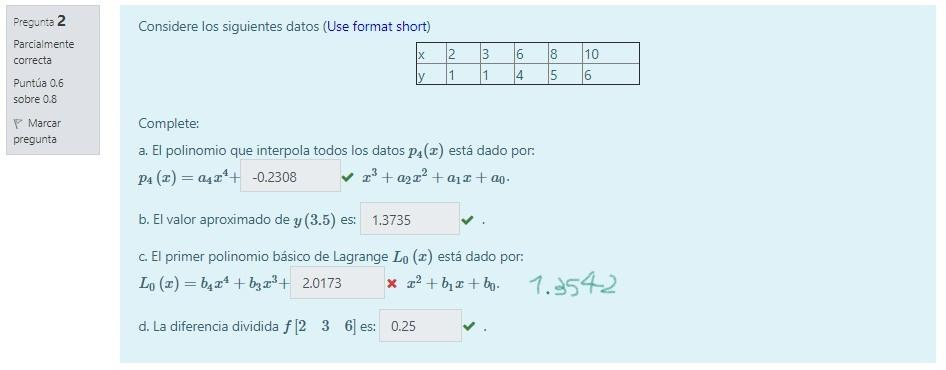

X = [2 3 6 8 10];
Y = [1 1 4 5 6];
[C, D] = newpoly (X, Y) 

C =     0.0091   -0.2308    2.0173   -6.2911    7.2143


D =     1.0000         0         0         0         0
    1.0000         0         0         0         0
    4.0000    1.0000    0.2500         0         0
    5.0000    0.5000   -0.1000   -0.0583         0
    6.0000    0.5000         0    0.0143    0.0091


polyval(C,3.5)

ans = 1.3735

[C, L] = lagran (X, Y)

C =     0.0091   -0.2308    2.0173   -6.2911    7.2143


L =     0.0052   -0.1406    1.3542   -5.4375    7.5000
   -0.0095    0.2476   -2.2476    8.1524   -9.1429
    0.0104   -0.2396    1.8333   -5.2917    5.0000
   -0.0083    0.1750   -1.2167    3.3000   -3.0000
    0.0022   -0.0424    0.2768   -0.7232    0.6429
